load('Torque.mat');
Tnet = zeros(5,73); %matrix of net torque
for k=1:5
    Tnet(k,:) = T(k,:) - ((pi/18)*trapz(T(k,:)))/(4*pi);  % Subtracting average torque from each torque value 
    ((pi/18)*trapz(T(k,:)))/(4*pi)
    %figure
    %plot(theta, T(k,:))
% This will give us net torque acting on flywheel    
end

ans =      5.609421025143942e+02


ans =      5.271860304786036e+02


ans =      5.259194880381712e+02


ans =      4.538103295037633e+02


ans =      6.175119434569317e+02


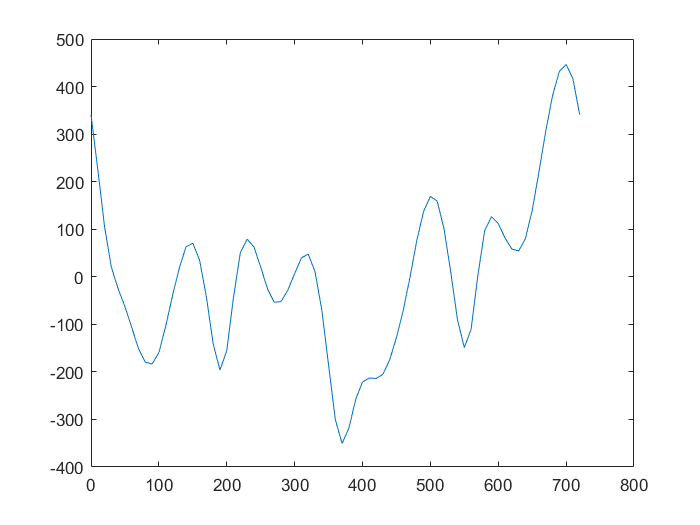

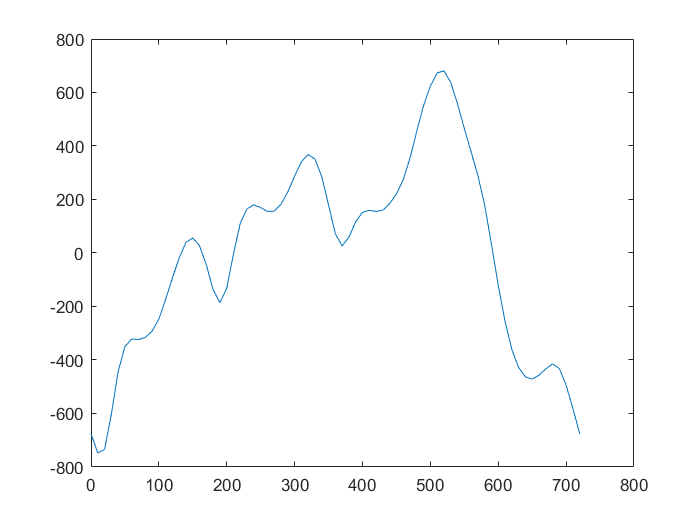

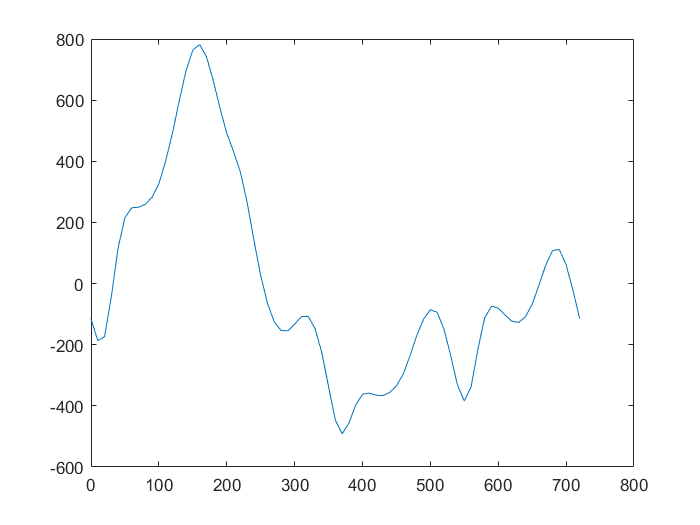

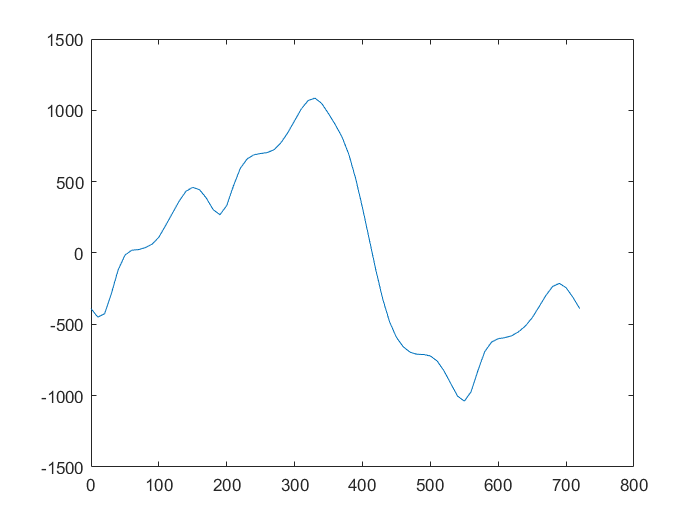

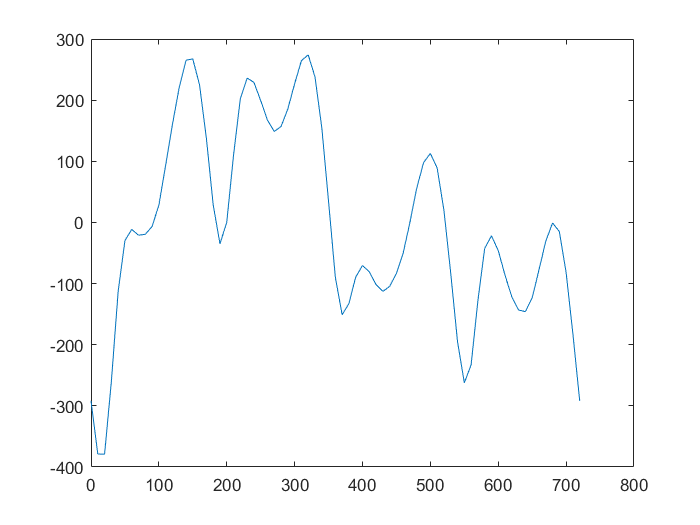


Energy = zeros(5,73);  %energy matrix
for k=1:5
    for k1=1:73
        Energy(k,k1) = (pi/18)*trapz(Tnet(k,1:k1));
    end
    Eavg=((pi/18)*trapz(Energy(k,:)))/(4*pi);
    Energy(k,:)=Energy(k,:)-Eavg;                           %making average energy datum
    figure
    plot(theta, Energy(k,:))
    Energy(k,:)=Energy(k,:)+0.5*J_system*Wavg^2;            %getting the actual energy.
    %Average angular velocity assumed same for all.
end

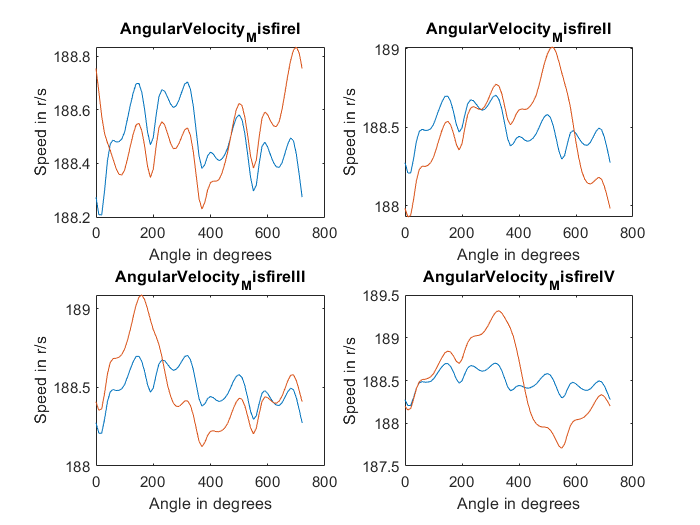

angular_velocity = zeros(5,73);                             %angular velocity matrix
for k=1:5
    angular_velocity(k,:) = ((2/J_system)*Energy(k,:)).^0.5;
end
subplot(2,2,1)
plot(theta,angular_velocity(5,:),theta,angular_velocity(1,:))
title('AngularVelocity_MisfireI')
xlabel('Angle in degrees')
ylabel('Speed in r/s')
subplot(2,2,2)
plot(theta,angular_velocity(5,:),theta,angular_velocity(2,:))
title('AngularVelocity_MisfireII')
xlabel('Angle in degrees')
ylabel('Speed in r/s')
subplot(2,2,3)
plot(theta,angular_velocity(5,:),theta,angular_velocity(3,:))
title('AngularVelocity_MisfireIII')
xlabel('Angle in degrees')
ylabel('Speed in r/s')
subplot(2,2,4)
plot(theta,angular_velocity(5,:),theta,angular_velocity(4,:))
title('AngularVelocity_MisfireIV')
xlabel('Angle in degrees')
ylabel('Speed in r/s')

wavg_healthycalc = (pi/18)*trapz(angular_velocity(5,:))/(4*pi)

wavg_healthycalc =      1.884955210994954e+02
